# D Flip Flop from Logic Gates Timing Diagram

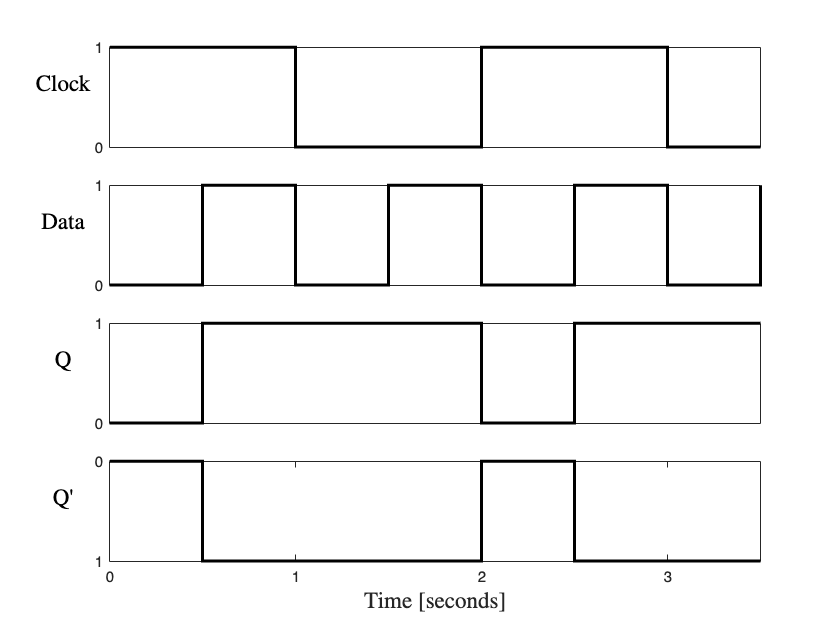

time = 0:1:7; 

%Data
clock_signal = [1 1 0 0 1 1 0 0]; 
data_signal = [0 1 0 1 0 1 0 1]; 
Q_signal = [0 1 1 1 0 1 1 1]; 

% Plotting the clock signal
subplot(4,1,1);
stairs(time, clock_signal, 'k', 'LineWidth', 2);
ylim([0 1]);
title('Clock');
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('Clock', 'Position', [-.5, 0.5],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

% Plotting the data signal
subplot(4,1,2);
stairs(time, data_signal, 'k', 'LineWidth', 2);
ylim([0 1]);
xticks([]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
title('Data', 'Position', [-.5, 0.5],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

% Plotting the Q signal
subplot(4,1,3);
stairs(time, Q_signal, 'k', 'LineWidth', 2);
ylim([0 1]);
xticks([]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
title('Q', 'Position', [-.5, 0.5],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

% Generating Q' signal by negating Q_signal
Qbar_signal = ~Q_signal;

% Plotting the Q' signal
subplot(4,1,4);
stairs(time, Qbar_signal, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'1', '0'});
xticks(0:2:10); % Set the x-axis ticks for the Q' subplot
xticklabels({'0', '1', '2', '3'}); % Set the x-axis labels for the Q' subplot
title('Q''', 'Position', [-.5, 0.5],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left


xlabel('Time [seconds]','Interpreter', 'latex', 'FontSize',15);
%Saving the image
saveas(gcf, 'logic_gates.png');

# D Flip Flop as Frequency Divider

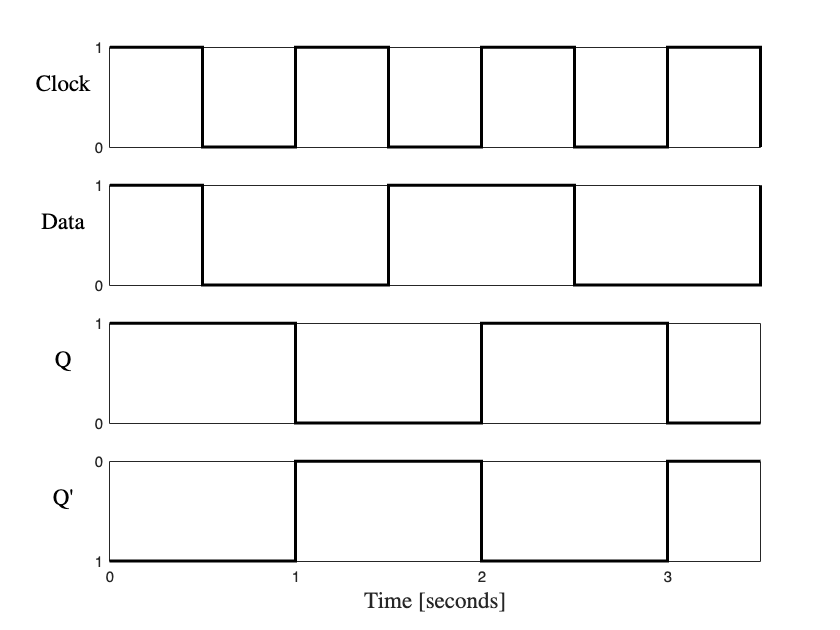


time = 0:1:7; 

%Data
clock_signal = [ 1 0 1 0 1 0 1 0]; 
data_signal = [ 1 0 0 1 1 0 0 1]; 
Q_signal = [1 1 0 0 1 1 0 0]; 

% Plotting the clock signal
subplot(4,1,1);
stairs(time, clock_signal, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('Clock', 'Position', [-.5, 0.5],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

% Plotting the data signal
subplot(4,1,2);
stairs(time, data_signal, 'k', 'LineWidth', 2);
ylim([0 1]);
xticks([]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
title('Data', 'Position', [-.5, 0.5],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

% Plotting the Q signal
subplot(4,1,3);
stairs(time, Q_signal, 'k', 'LineWidth', 2);
ylim([0 1]);
xticks([]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
title('Q', 'Position', [-.5, 0.5],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

% Generating Q' signal by negating Q_signal
Qbar_signal = ~Q_signal;

% Plotting the Q' signal
subplot(4,1,4);
stairs(time, Qbar_signal, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'1', '0'});
xticks(0:2:10); % Set the x-axis ticks for the Q' subplot
xticklabels({'0', '1', '2', '3'}); % Set the x-axis labels for the Q' subplot
title('Q''', 'Position', [-.5, 0.5],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left


xlabel('Time [seconds]','Interpreter', 'latex', 'FontSize',15);
saveas(gcf, 'frequency_divider.png');

# D Flip Flop as 2-bit Counter

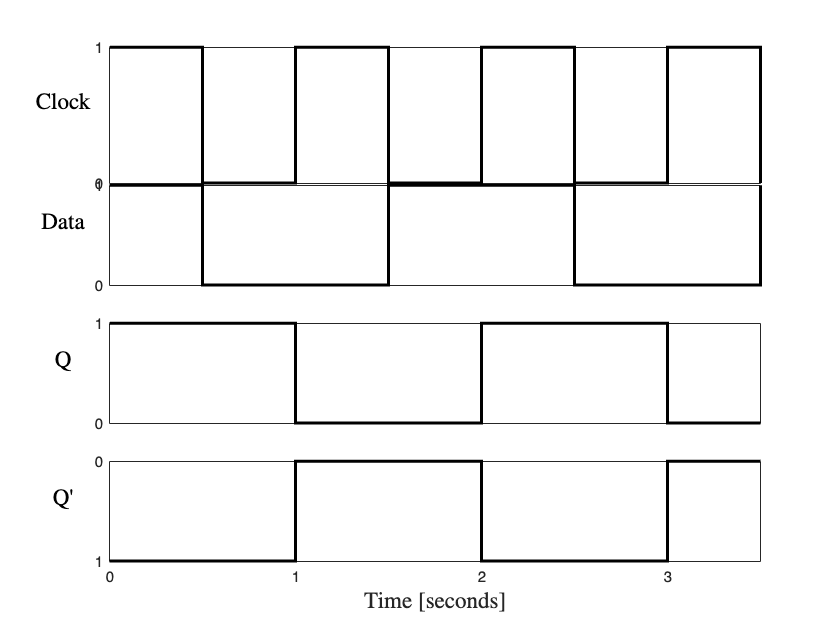


time = 0:1:7; 

%Data
clock_signal = [1 0 1 0 1 0 1 0 ]; 
Q_signal_1 = [0 0 1 1 0 0 1 1 ]; 
Q_signal_2 = [0 0 0 0 1 1 1 1 ]; 

% Plotting the clock signal
subplot(3,1,1);
stairs(time, clock_signal, 'k', 'LineWidth', 2);
ylim([0 1]);
title('Clock');
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('Clock', 'Position', [-.5, 0.5],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

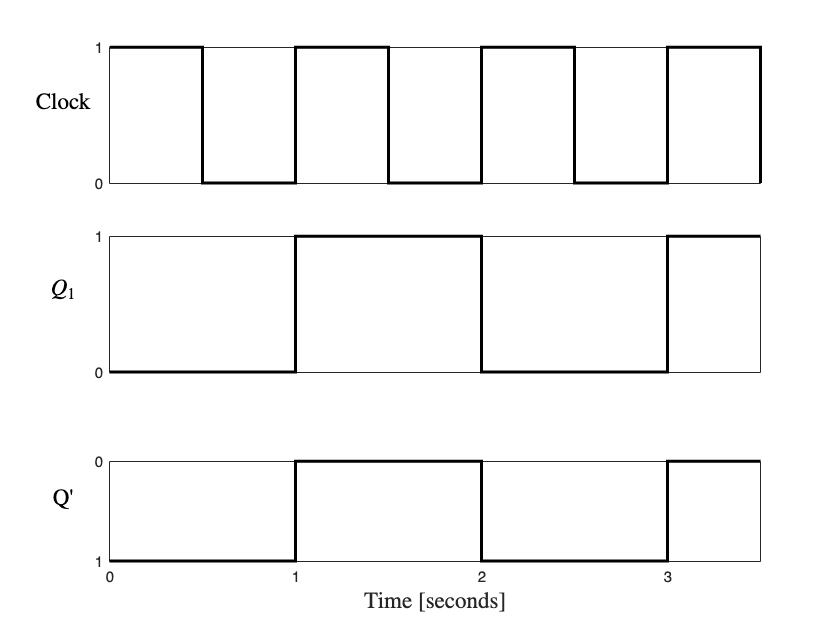


% Plotting the data signal
subplot(3,1,2);
stairs(time, Q_signal_1, 'k', 'LineWidth', 2);
ylim([0 1]);
xticks([]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
title('$Q_1$', 'Position', [-.5, 0.5],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

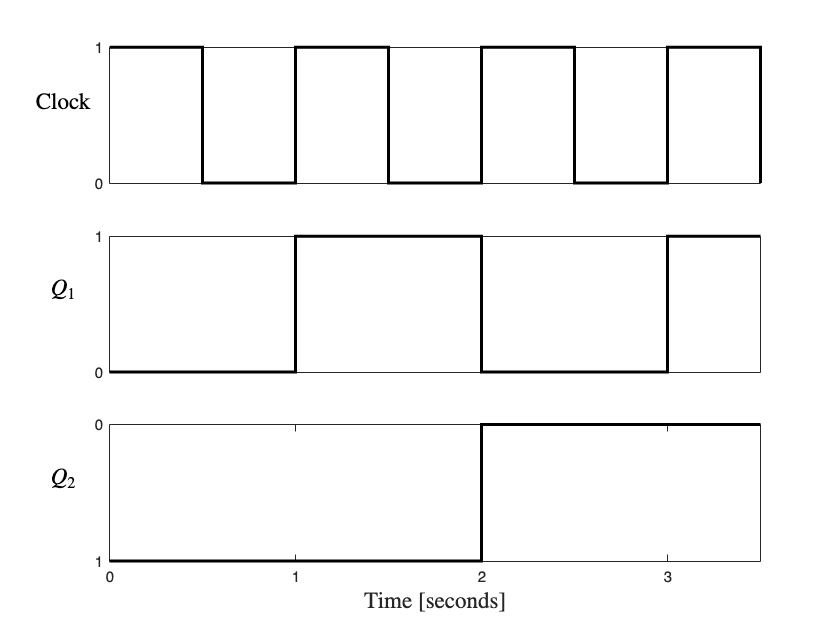



% Plotting the Q' signal
subplot(3,1,3);
stairs(time, Q_signal_2, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'1', '0'});
xticks(0:2:10); % Set the x-axis ticks for the Q' subplot
xticklabels({'0', '1', '2', '3'}); % Set the x-axis labels for the Q' subplot
title('$Q_2$', 'Position', [-.5, 0.5],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left


xlabel('Time [seconds]','Interpreter', 'latex', 'FontSize',15);

saveas(gcf, '2_bit_counter.png');

# D Flip Flop as 2-bit Counter but ends at 10

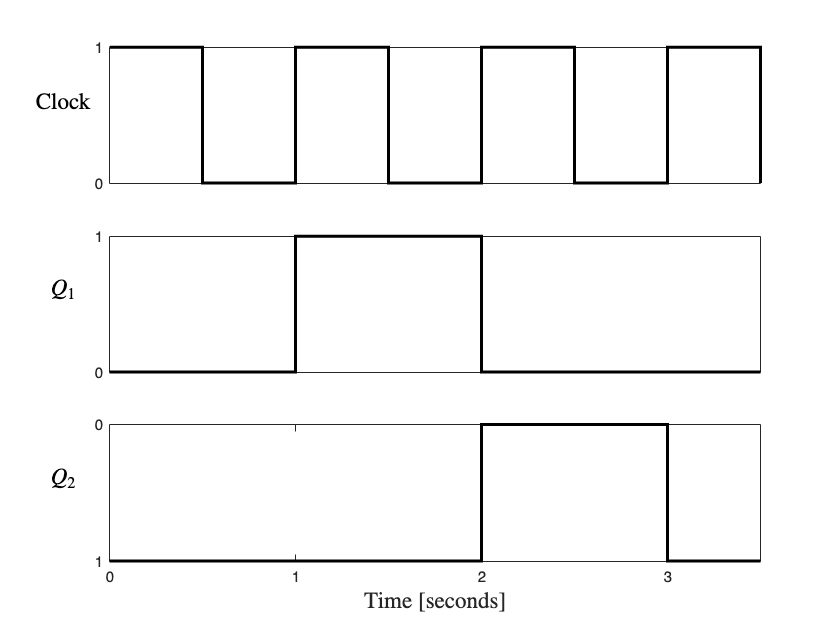

time = 0:1:7; 

%Data
clock_signal = [1 0 1 0 1 0 1 0 ]; 
Q_signal_1 = [0 0 1 1 0 0 0 0 ]; 
Q_signal_2 = [0 0 0 0 1 1 0 0 ]; 

% Plotting the clock signal
subplot(3,1,1);
stairs(time, clock_signal, 'k', 'LineWidth', 2);
ylim([0 1]);
title('Clock');
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('Clock', 'Position', [-.5, 0.5],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left

% Plotting the data signal
subplot(3,1,2);
stairs(time, Q_signal_1, 'k', 'LineWidth', 2);
ylim([0 1]);
xticks([]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
title('$Q_1$', 'Position', [-.5, 0.5],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left


% Plotting the Q' signal
subplot(3,1,3);
stairs(time, Q_signal_2, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'1', '0'});
xticks(0:2:10); % Set the x-axis ticks for the Q' subplot
xticklabels({'0', '1', '2', '3'}); % Set the x-axis labels for the Q' subplot
title('$Q_2$', 'Position', [-.5, 0.5],'Interpreter', 'latex', 'FontSize', 15); % Adjust the 'Position' property to align the title to the left


xlabel('Time [seconds]','Interpreter', 'latex', 'FontSize',15);
saveas(gcf, '2_bit_counter_10.png');

# D Flip Flop as Shift Register connected to 5V

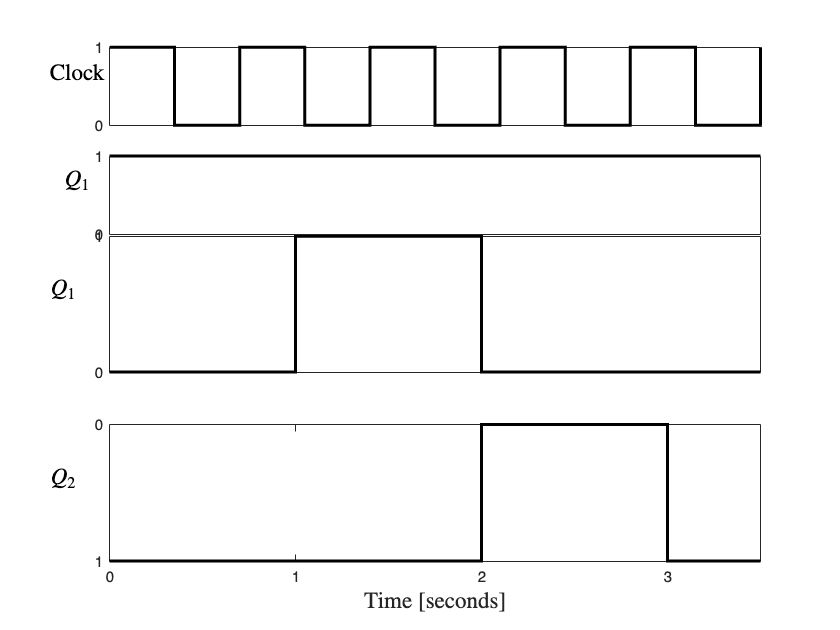

time = 0:1:10;

clock = [1 0 1 0 1 0 1 0 1 0 1 ];
Q_1 = [1 1 1 1 1 1 1 1 1 1 1];
Q_2 = [0 0 1 1 1 1 1 1 1 1 1];
Q_3 = [0 0 0 0 1 1 1 1 1 1 1];
Q_4 = [0 0 0 0 0 0 1 1 1 1 1];

%Plot the clock
subplot(5,1,1);
stairs(time, clock, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('Clock', 'Position', [-.5,0.5],'Interpreter', 'latex', 'FontSize', 15);

%Plot the q_1
subplot(5,1,2);
stairs(time, Q_1, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('$Q_1$', 'Position', [-.5,0.5],'Interpreter', 'latex', 'FontSize', 15);

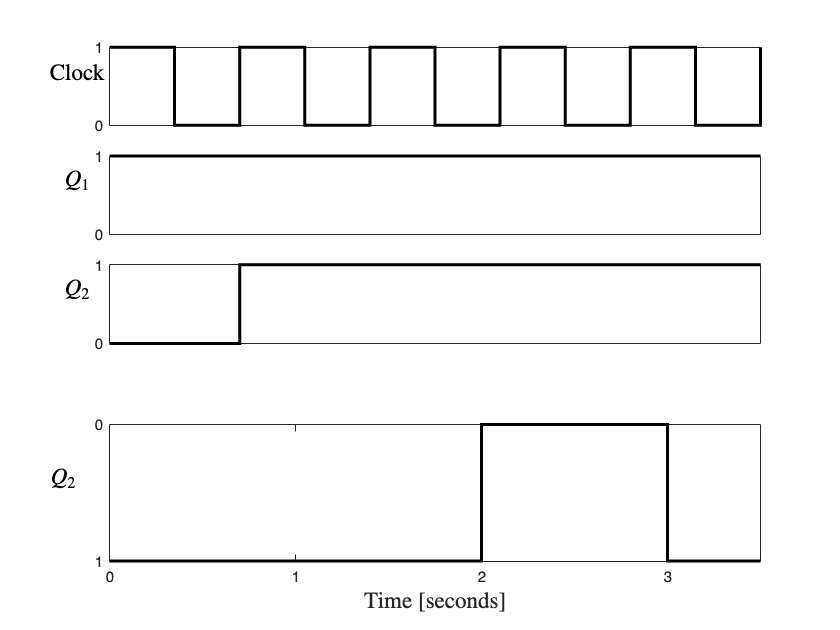


%Plot the q_2
subplot(5,1,3);
stairs(time, Q_2, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('$Q_2$', 'Position', [-.5,0.5],'Interpreter', 'latex', 'FontSize', 15);

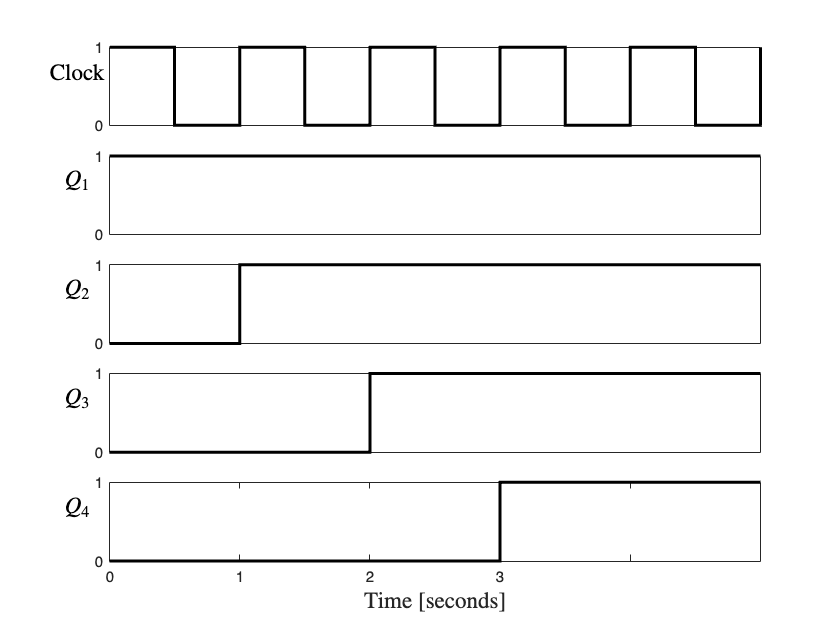


%Plot the q_3
subplot(5,1,4);
stairs(time, Q_3, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('$Q_3$', 'Position', [-.5,0.5],'Interpreter', 'latex', 'FontSize', 15);

%Plot the q_4

subplot(5,1,5);
stairs(time, Q_4, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
title('$Q_4$', 'Position', [-.5,0.5],'Interpreter', 'latex', 'FontSize', 15);
xticks(0:2:10); 
xticklabels({'0', '1', '2', '3'});

xlabel('Time [seconds]','Interpreter', 'latex', 'FontSize',15);

saveas(gcf, 'shift_register_5V.png');

# D Flip Flop as Shift Register connected to Ground

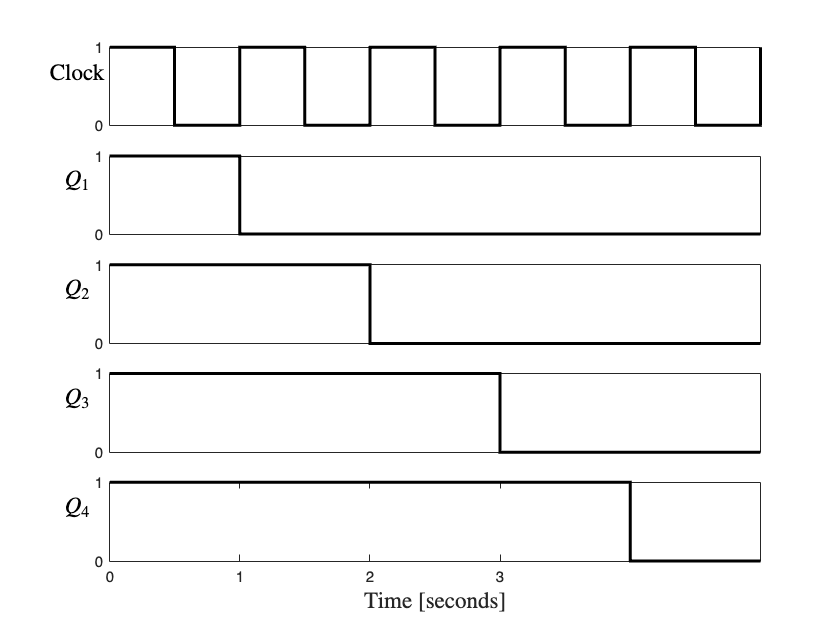

time = 0:1:10;

clock = [1 0 1 0 1 0 1 0 1 0 1 ];
Q_1 = [1 1 0 0 0 0 0 0 0 0 0];
Q_2 = [1 1 1 1 0 0 0 0 0 0 0];
Q_3 = [1 1 1 1 1 1 0 0 0 0 0];
Q_4 = [1 1 1 1 1 1 1 1 0 0 0];

%Plot the clock
subplot(5,1,1);
stairs(time, clock, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('Clock', 'Position', [-.5,0.5],'Interpreter', 'latex', 'FontSize', 15);

%Plot the q_1
subplot(5,1,2);
stairs(time, Q_1, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('$Q_1$', 'Position', [-.5,0.5],'Interpreter', 'latex', 'FontSize', 15);

%Plot the q_2
subplot(5,1,3);
stairs(time, Q_2, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('$Q_2$', 'Position', [-.5,0.5],'Interpreter', 'latex', 'FontSize', 15);

%Plot the q_3
subplot(5,1,4);
stairs(time, Q_3, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('$Q_3$', 'Position', [-.5,0.5],'Interpreter', 'latex', 'FontSize', 15);

%Plot the q_4

subplot(5,1,5);
stairs(time, Q_4, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
title('$Q_4$', 'Position', [-.5,0.5],'Interpreter', 'latex', 'FontSize', 15);
xticks(0:2:10); 
xticklabels({'0', '1', '2', '3'});

xlabel('Time [seconds]','Interpreter', 'latex', 'FontSize',15);

saveas(gcf, 'shift_register_ground.png');

# Shift Register with Toggle

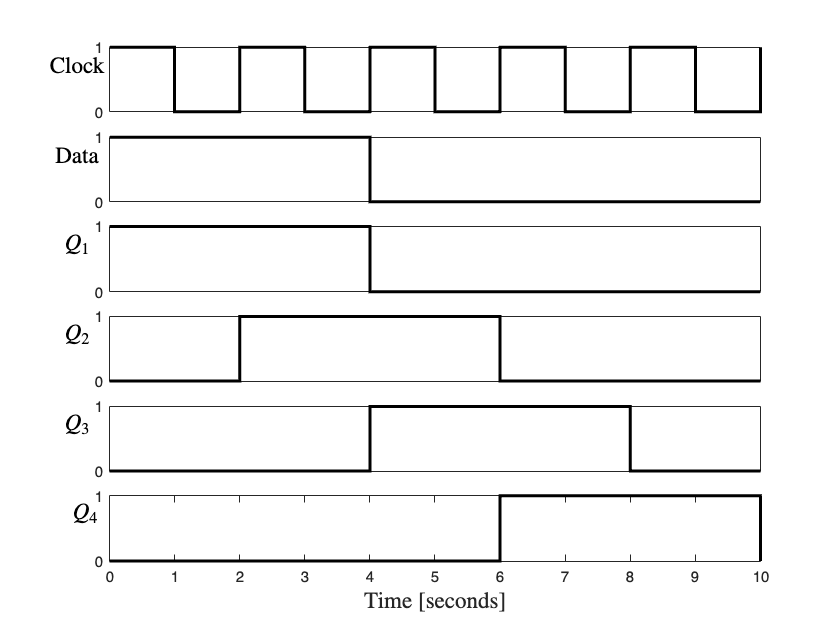

time = 0:1:20;

clock = [1 1 0 0 1 1 0 0 1 1 0 0 1 1 0 0 1 1 0 0 1 ];
data = [1 1 1 1 1 1 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 ];
Q_1 = [1 1 1 1 1 1 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 ];
Q_2 = [0 0 0 0 1 1 1 1 1 1 1 1 0 0 0 0  0 0 0 0 0  ];
Q_3 = [0 0 0 0 0 0 0 0 1 1 1 1 1 1 1 1 0 0 0 0 0 ];
Q_4 = [0 0 0 0 0 0 0 0 0 0 0 0 1 1 1 1 1 1 1 1 0 ];

%Plot the clock
subplot(6,1,1);
stairs(time, clock, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('Clock', 'Position', [-1,0.5],'Interpreter', 'latex', 'FontSize', 15);

%Plot the data
subplot(6,1,2);
stairs(time, data, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('Data', 'Position', [-1,0.5],'Interpreter', 'latex', 'FontSize', 15);


%Plot the q_1
subplot(6,1,3);
stairs(time, Q_1, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('$Q_1$', 'Position', [-1,0.5],'Interpreter', 'latex', 'FontSize', 15);

%Plot the q_2
subplot(6,1,4);
stairs(time, Q_2, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('$Q_2$', 'Position', [-1,0.5],'Interpreter', 'latex', 'FontSize', 15);

%Plot the q_3
subplot(6,1,5);
stairs(time, Q_3, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
xticks([]);
title('$Q_3$', 'Position', [-1,0.5],'Interpreter', 'latex', 'FontSize', 15);

%Plot the q_4

subplot(6,1,6);
stairs(time, Q_4, 'k', 'LineWidth', 2);
ylim([0 1]);
set(gca, 'YTick', [0 1], 'YTickLabel', {'0', '1'});
title('$Q_4$', 'Position', [-.75,0.5],'Interpreter', 'latex', 'FontSize', 15);
xticks(0:2:20); 
xticklabels({'0', '1', '2', '3', '4', '5', '6', '7', '8', '9', '10'});

xlabel('Time [seconds]','Interpreter', 'latex', 'FontSize',15);

saveas(gcf, 'shift_register_toggle.png');